% Created by Kuan-Min Lee Feb. 10th, 2023

**This MATLAB Live Script File is created for Homework 1 from ENGN1930B Course**

**Insrtuctor: Prof. Jonghwan Lee**

**Name: Kuan-Min Lee**

**Brown ID: 140481859**

**Problem 1.1:**

This problem follows similar setting for the environment setup in figure 1.2. As for the difference is the x_samp for this problem, it becomes 0 since now we would like to focus on the point at the bottom. To start with this problem, it begins with setting up symbolic computation for the environment.

**Symbolic Computation: **

clear

syms f z_samp x_samp positive % setting up focal length, sample distance, 
                              % sample distance in respect to optical axis as positive
syms theta_samp z positive % setting up input light source angle, and z value as positive
assume(z_samp > f)

rIn = [x_samp; theta_samp]; % setting up input ray storage in cylindrical coordinate
rIn % show r_in

$$rIn = \left(\begin{array}{c} x_{\mathrm{samp}}\\ \theta_{\mathrm{samp}} \end{array}\right)$$

Then, we will set up the RTM for the entire system, which include the RTM for the air of the sample side, RTM for the lens, and the RTM for the air on the image side:

rtmSys = [1 z; 0 1]*[1 0;-1/f 1]*[1 z_samp;0 1]; % setting up rtm for the entire system (RTM_air*RTM_len*RTM_airsample)
rtmSys % show RTM for the entire system

$$rtmSys = \left(\begin{array}{cc} 1-\frac{z}{f} & z-z_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)\\ -\frac{1}{f} & 1-\frac{z_{\mathrm{samp}}}{f} \end{array}\right)$$

The output ray will be calculated as the product of RTM of the entire system and the input ray:

rOut = rtmSys * rIn; % define the output ray
rOut

$$rOut = \left(\begin{array}{c} \theta_{\mathrm{samp}}\,\left(z-z_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)\\ -\frac{x_{\mathrm{samp}}}{f}-\theta_{\mathrm{samp}}\,\left(\frac{z_{\mathrm{samp}}}{f}-1\right) \end{array}\right)$$

The x, which happens to be the distance between the light source and the optical axis , will be stored as the first element of the output ray:

xOut(z,theta_samp,f,z_samp,x_samp) = -rOut(1); % define where x value is stored in
xOut

$$xOut(z, theta\_samp, f, z\_samp, x\_samp) = x_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)-\theta_{\mathrm{samp}}\,\left(z-z_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)\right)$$

xOutDiff(z,f,z_samp,x_samp) = ...
    xOut(z,0,f,z_samp,x_samp) - xOut(z,0.1,f,z_samp,x_samp)

$$xOutDiff(z, f, z\_samp, x\_samp) = \frac{z}{10}-\frac{z_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)}{10}$$

We will solve for the z location where the rays emerge. Therefore, in such a case, the difference of x for different angles (in our case, they are 0 and 0.1 rad) should be 0:

zImg(f,z_samp,x_samp) = solve(xOutDiff==0,z); % setting up the equation for solving for image formation location

We are aiming to solve for the condition, where the x_samp = 0 with focal length as 100 and z_samp as 150 mm away from the lens:

[zImg(f,z_samp,x_samp),soloPara, solCond] = ...
    solve(xOutDiff==0, z,ReturnConditions=true);
zImg(100,150,0)

$$ans = 300$$

From the example of figure 1.2, the distance where the rays emerge is also located at 300 mm. Therefore, no matter where the light source is, all light rays emerge at this location.

**Problem 1.2**

In this problem, we repeat the same calculation for all the point on the objective light source, which will include x varies from 0 to 20 using numerical computation.To start with this problem, we begin with some numerical computation setting for the system:

**Numerical Computation:**

clear 
f = 100; % setting up focal length
xSamp = 0:20; % setting up x varies from 0 to 20 mm
thSamp = linspace(-pi/8,pi/8,9); % setting up angle varies from -pi/8 rad to pi/8 rad 
zSamp = -150; % setting up sample location as 150 mm away from the lens
              % (negative since it's on opposite of the lens)

Then we set up the z axis limitation and as well as how many paramters we will need to test with: number of x_samp, and number of angles.

dz = 1;
zEnd = 400;
z = zSamp:dz:zEnd;
nx = numel(xSamp);
nth = numel(thSamp);
nz = numel(z);

Setting up RTM for Lens and Air for the system:

rtmLens = [1 0;-1/f 1];
rtmAir = [1 dz;0 1];

After all setting, we are moving forward to calculating the ray propagation:

r = zeros(2,nz,nx,nth); % setup r array for storage

% looping through each angle
for ith = 1:nth
    theta1 = thSamp(ith);
    % looping through each x location
    for ix = 1:nx
        x1 = xSamp(ix);
        % for one specific angle and x location, 
        % create a temporarily r storage for calculation
        r1 = zeros(2,nz);
        r1(:,1) = [x1;theta1];
        % looping through each location
        for iz = 2:nz
            r1(:,iz) = rtmAir * r1(:,iz-1);
            if z(iz) == 0
               r1(:,iz) = rtmLens*r1(:,iz);
            end
        end
        r(:,:,ix,ith) = r1;
    end
end

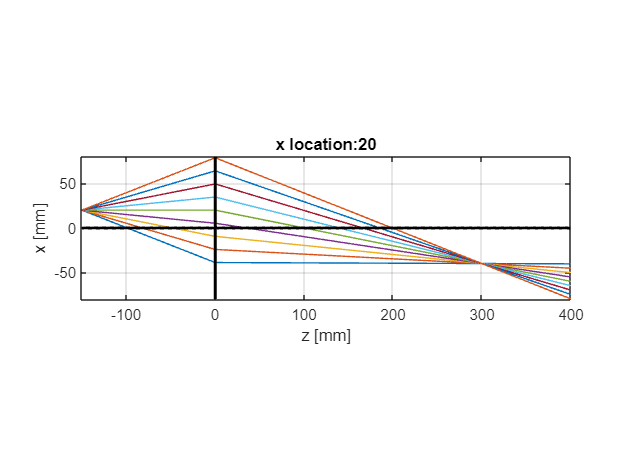

figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

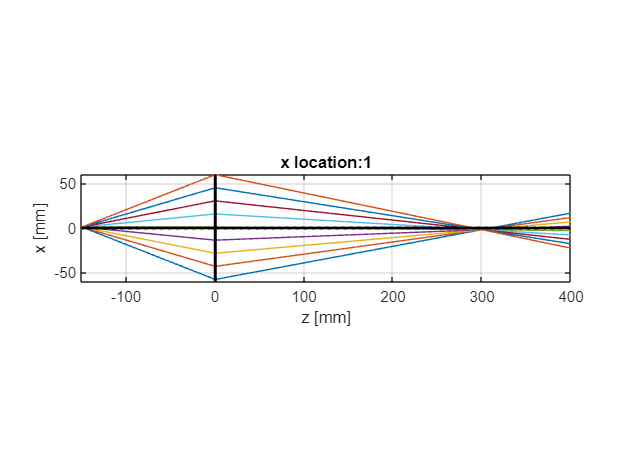

ix = 2;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

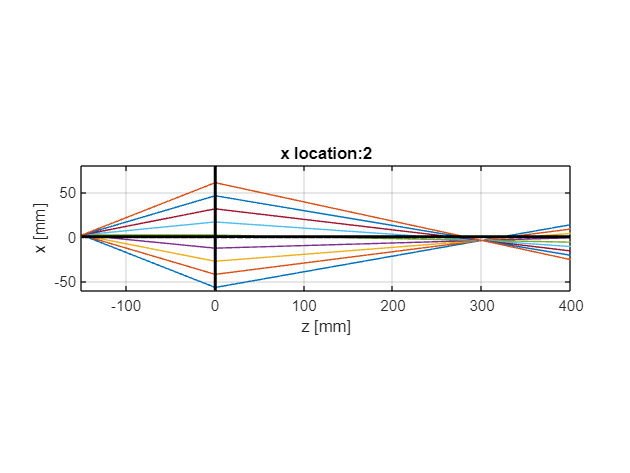

ix = 3;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

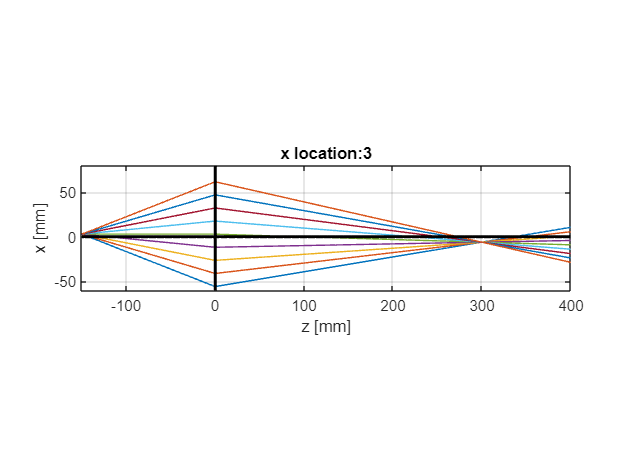

ix = 4;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

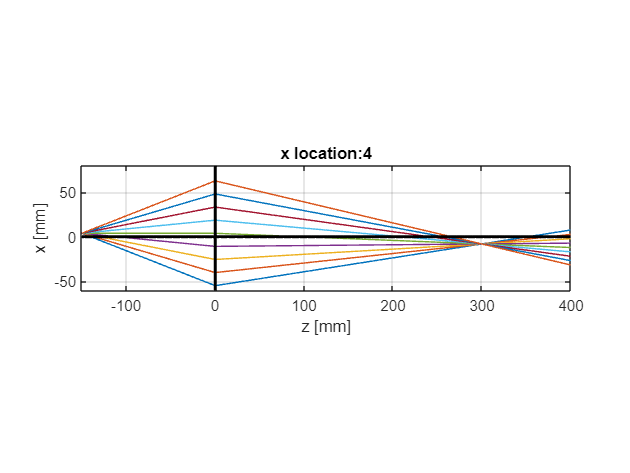

ix = 5;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

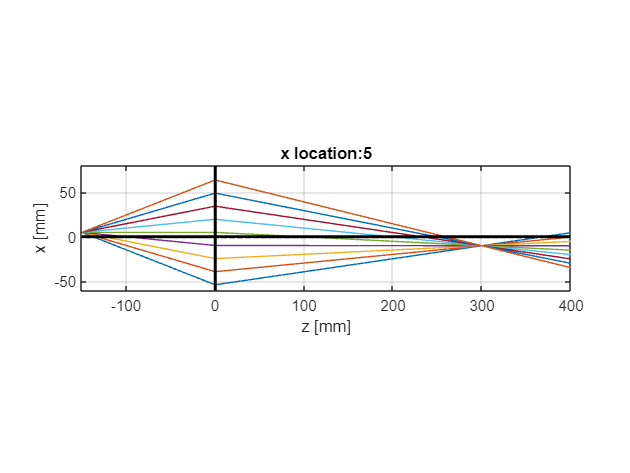

ix = 6;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

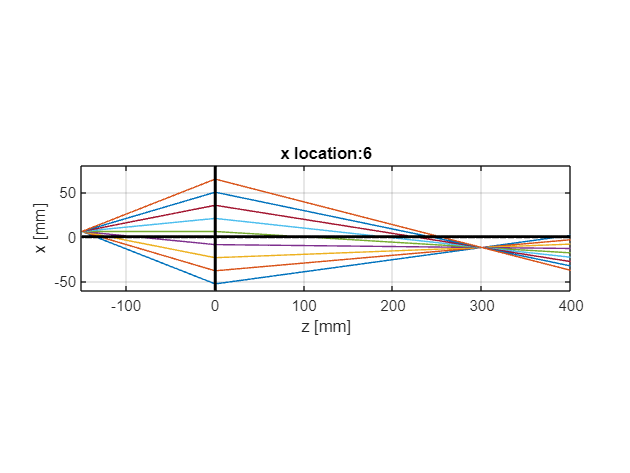

ix = 7;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

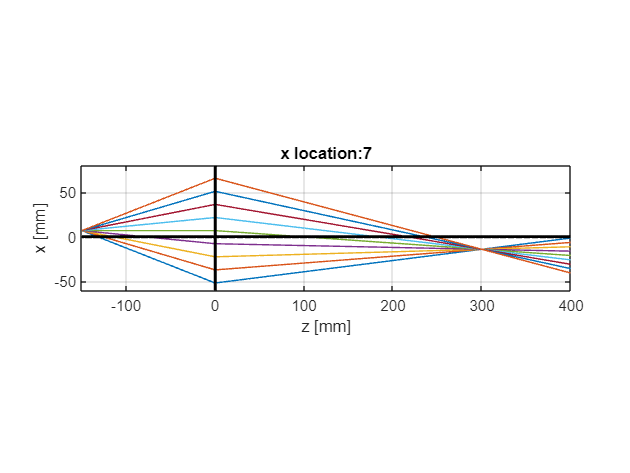

ix = 8;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

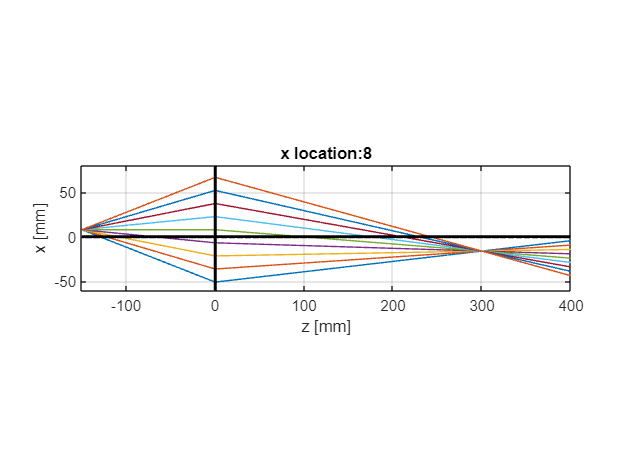

ix = 9;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

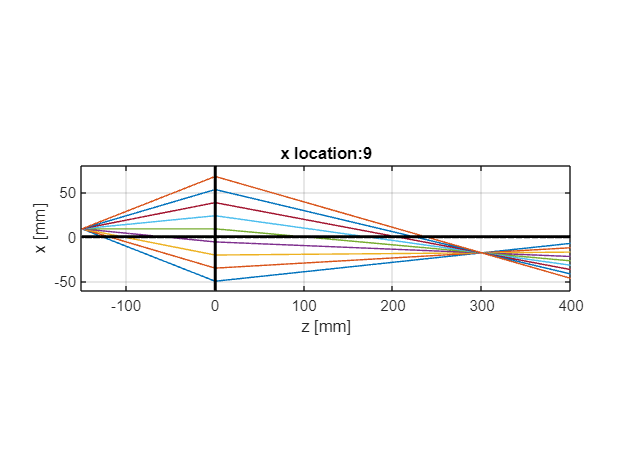

ix = 10;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

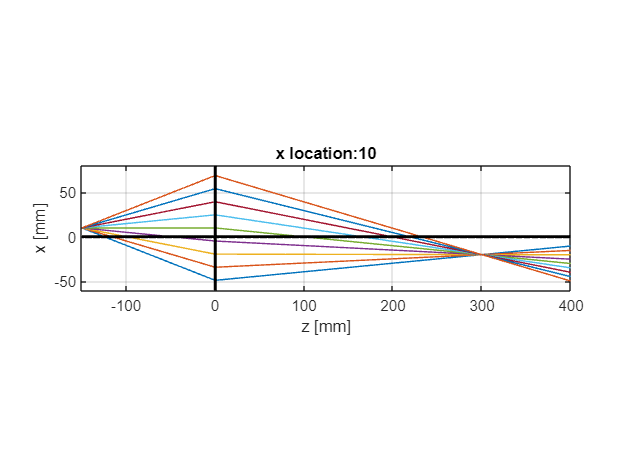

ix = 11;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

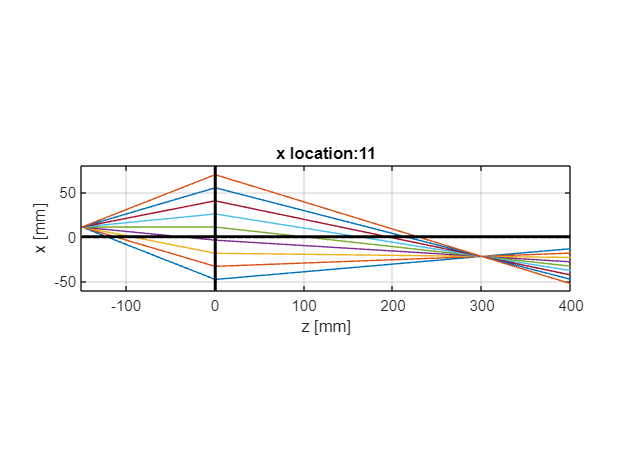

ix = 12;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

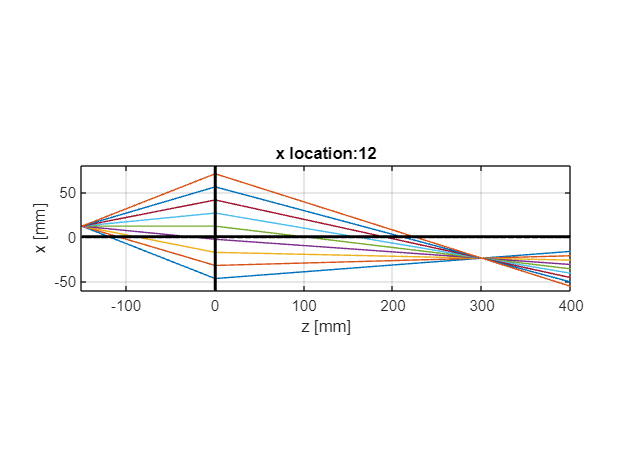

ix = 13;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

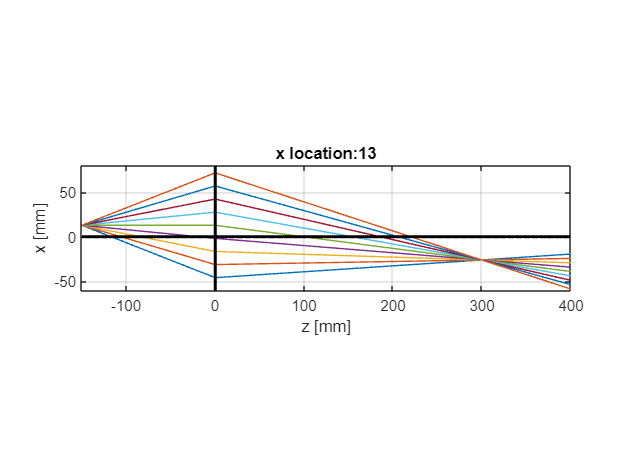

ix = 14;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

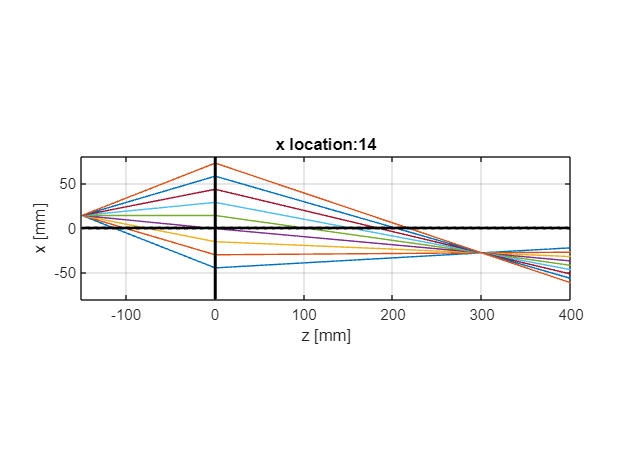

ix = 15;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

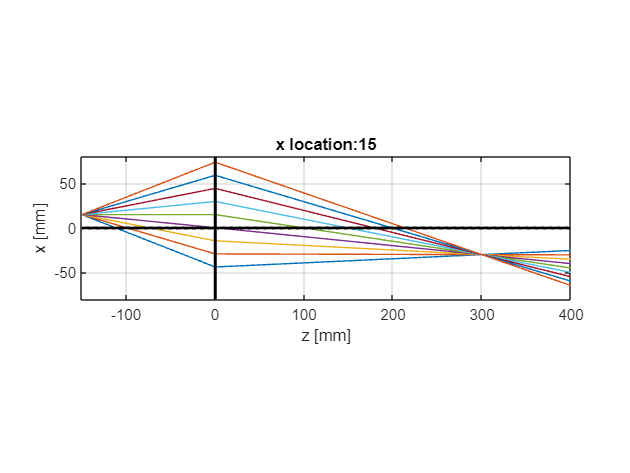

ix = 16;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

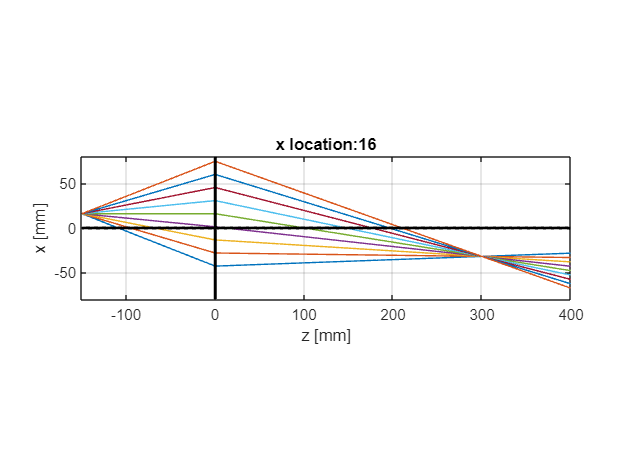

ix = 17;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

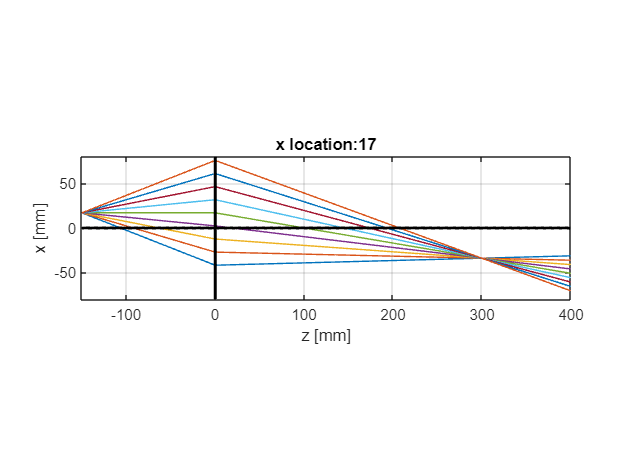

ix = 18;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

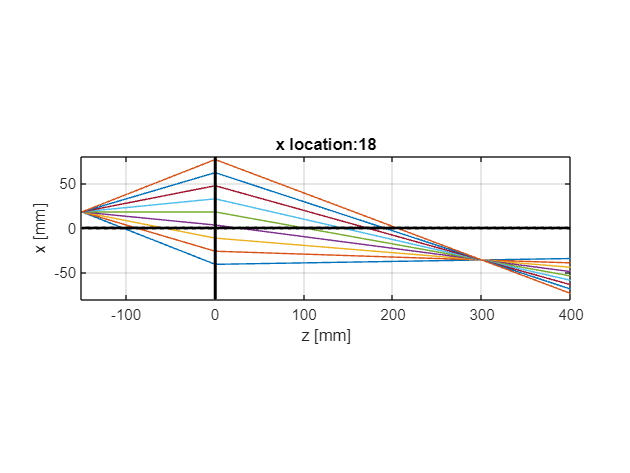

ix = 19;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

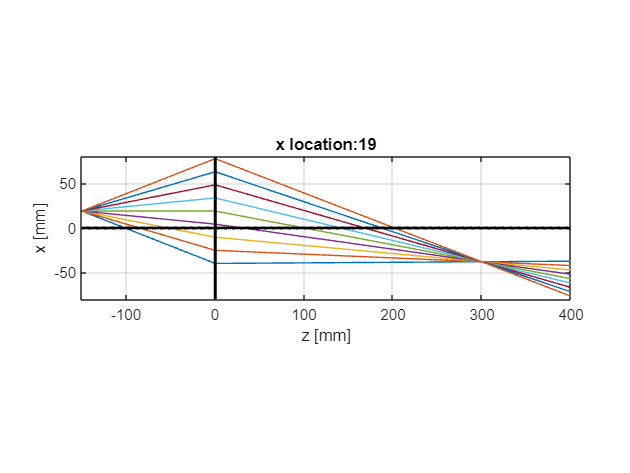

ix = 20;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

ix = 21;
figure(ix)
num = string(ix-1);
graph_name = strcat('x location: ',num);
plot(z,squeeze(squeeze(r(1,:,ix,:))));
line(z,zeros(size(z)),color='k',Linewidth=2);
line([0 0],get(gca,'ylim'),color='k',LineWidth=2);
title(graph_name);
grid on;
axis image
xlabel('z [mm]')
ylabel('x [mm]')

**Problem 1.3:**

**(a) **For this portion of the problem, we will need to find the numerical aperture of a lens with focal length f that will be able to collimate the light without any energy loss.

Based on the description of the previous problem statement, the light source is collimated, then we can place the object at the distance of one focal length away from the lens,

Therefore, the following statement is true:

syms diameter f positive
theta = (diameter/2)/f

$$theta = \frac{\mathrm{diameter}}{2\,f}$$

syms theta f 
diameter = 2*theta*f

$$diameter = 2\,f\,\theta$$

**(b) **For this portion of the problem, the light source is no longer an ideal light source, which has a diamter of D_src and generates rays within a sufficiently large angle. A lens  with focal length f has been utilized to collimate the light source, and the diverging angle can be calculated as:

syms diameter_lens diameter_src positive
diverging_angle = (-1)*2*atan(((diameter_lens-diameter_src)/2)/f)

$$diverging\_angle = 2\,\mathrm{atan}\left(\frac{\frac{{\mathrm{diameter}}_{\mathrm{src}}}{2}-\frac{{\mathrm{diameter}}_{\mathrm{lens}}}{2}}{f}\right)$$